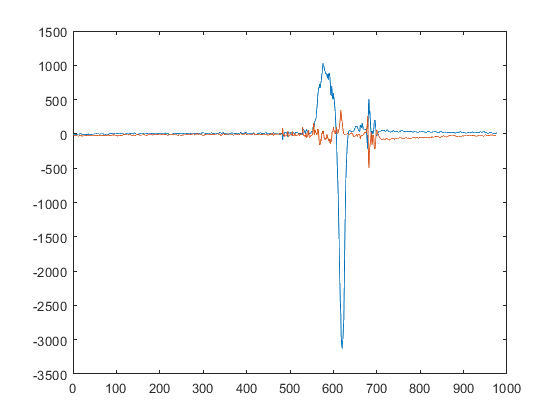

 %clc;clear;
 %load("aaRealData3.mat");
t= a(:,4);
ax = a(:,2);
ay = a(:,3);
%az = a(:,3);
%ax = ax-15;
%ay= ay +3;
plot([ax ay]);

## filter part for acceleration

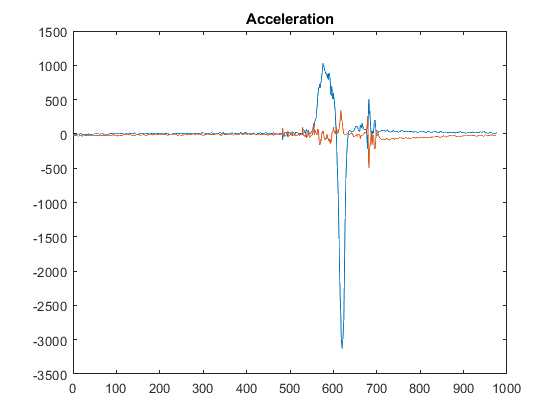

divider = 50;
divider2 = 20;
% ax = round(ax/divider);
% ay = round(ay/divider);
% az = round(az/divider);

% for i= 2:length(a)
%     if ax(i)<divider & ax(i)>-divider
%         if abs(ax(i)-ax(i-1))<divider2
%             ax(i) = 0;
%         end
%     end
%     
%     if ay(i)<divider & ay(i)>-divider
%         if abs(ay(i)-ay(i-1))<divider2
%             ay(i) = 0;
%         end
%     end
% end
% low_filt_coef = 0.01;
% ax = lowpass(ax,low_filt_coef);
% ay = lowpass(ay,low_filt_coef);
% maf_coef =20;%30
% ax = movmean(ax,maf_coef);
% ay = movmean(ay,maf_coef);
plot(ax); title("Acceleration");
hold on;
plot(ay);
hold off

## velocity integration

vx = 0.*ax;
vy = 0.*ay;
for i= 2:length(a)
    vx(i)=vx(i-1)+ax(i)*t(i);
    vy(i)=vy(i-1)+ay(i)*t(i);
    %vz(i)=sum(az(1:i));
end




## Filter part for velocity

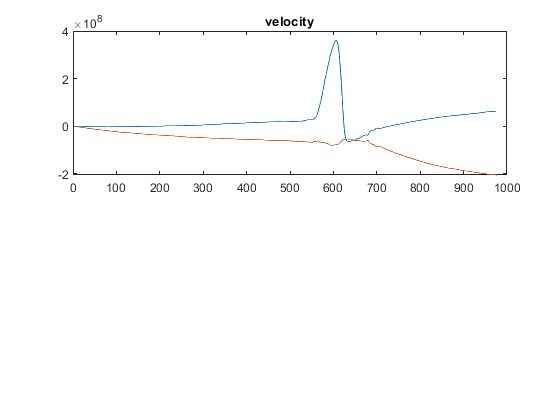

% high_filt_coef = 0.0001;%0.003
% highf = fir1(2,0.0001,"high",chebwin(10,20));
% vxf = filter(highf,1,vx);
% %vxf = highpass(vx,high_filt_coef);
% vyf = highpass(vy,high_filt_coef);

figure;
subplot(211);
plot(vx);title("velocity");
hold on;
plot(vy);
hold off

% subplot(212);
% plot(vxf);title("velocity Fitered");
% hold on;
% plot(vyf);
% hold off

## Distance calculation

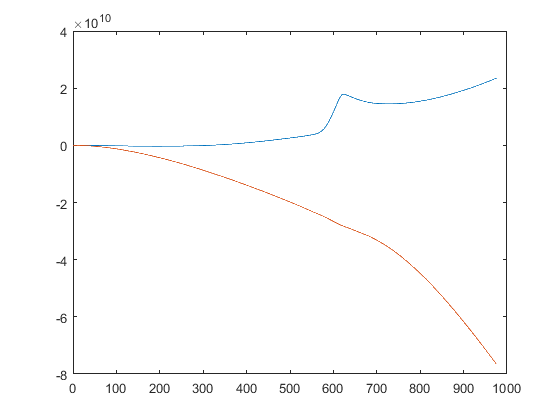

for i= 1:length(ax)
    xx(i)=sum(vx(1:i));
    yy(i)=sum(vy(1:i));
end
figure;
plot(xx);
hold on
plot(yy);

hold off;

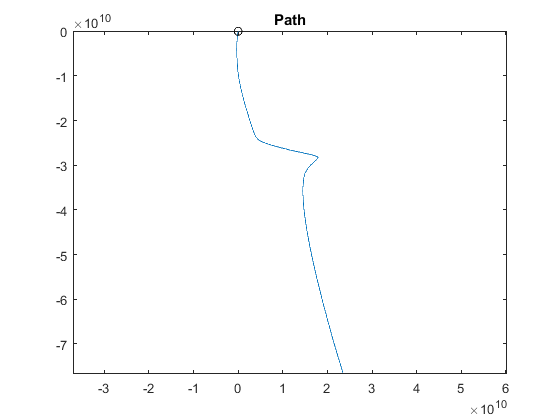

figure;
plot(xx,yy);title("Path");
hold on;
plot(xx(1),yy(1), 'ok');
hold off;
axis("equal")